# USV Draft

Write an equation for buoyancy equilibrium where the mass of the displaced volume is equal to the mass of the vessel.  Document the equation by writing it in your live script.

At equilibrium:


$$m_{vessel} = \rho_{water} \cdot v_{diplaced} $$



$$m_{vessel} = \rho_{water} \cdot  (L)\cdot \left( R^2\arccos\left(1-\frac{d}{R}\right) - \left(R-d\right)\sqrt{R^2-\left(R-d\right)^2}\right)$$


Rearrange the equation so that the right side is zero.  Our goal is to find values of `d` that are the roots of this equation.  Again, write the model as a mathematical expression in your live script.  In general, when using software to implement a complex expression, it is good practice to explicitly write the expression before starting the software implementation.  This is an aide because we have a clear idea of what the software algorithm is supposed to do.  If we skip this step, it is harder to debug because we don't know if there is a mistake in code or a mistake in the underlying model.


$$m_{vessel} - \left[ \rho_{water} \cdot  (L) \cdot \left( R^2\arccos\left(1-\frac{d}{R}\right) - \left(R-d\right)\sqrt{R^2-\left(R-d\right)^2}\right) \right] = 0$$


Write a MATLAB local function that implements this mathematical model.

function b = usv_balance(h)
    rho_water = 1000;
    r = 0.213;
    l = 5; 
    a = r^2*acos(1-h/r) - (r-h).*sqrt(r^2-(r-h).^2);
    v = 2*a*l;
    m_displaced = v*rho_water;
    m_usv = 200;
    b = m_usv - m_displaced;
end

Test the function with some reasonable values of `d` .  Keep in mind that the equation above, for submerged volume, is only applicable for  `d<=2*R` .  Verify your equilibrium equation changes sign as d goes form *small* to *large. *

If we use a very small value of `d`, we would expect that the that the mass of vessel would be much larger than the mass of the displaced water, so our expression would be positive - and the value would be close to the mass of the vessel. 

usv_balance(0)

ans = 200

On the other hand, if the value of `d` is large enough, we expect the mass of the displaced water to be larger than the mass of the vessel, so at some point we'll end up with a negative number.  Let's try a few values and see how the function output changes.  Keep in mind that the radius is 0.213

usv_balance(0.1)

ans = -54.9199

usv_balance(0.3)

ans = -872.6947

usv_balance(0.5)

ans = -1.2253e+03 - 1.8405e+02i

If `d` gets too large, we end up with a complex number, which we could have anticipated looking at the square root in our model.

usv_balance(-0.001)

ans = 2.0000e+02 + 2.7539e-01i

Ditto for a value of `d` less than zero.

Use the `fzero`  function to find a root near an initial guess for `d` .

Based on the tests above, we probably have some intuition that d should be in the rage between $\{0, 2R\}$, so anywhere in that rage shoudl give the same result.

d_init = 0;
d_equil = fzero(@usv_balance, d_init)

Exiting fzero: aborting search for an interval containing a sign change
    because complex function value encountered during search.
(Function value at -0.0282843 is 200+42.21127i.)
Check function or try again with a different starting value.


d_equil = NaN

This is  interesting result because the `fzero` function gets confused.  The first step of the algorithm is to try and find an interval with a sign change as indication of the interval were the algorithm could find a zero.  We'll have to make our initial guess larger.

d_init = 0.1;
d_equil = fzero(@usv_balance, d_init)

d_equil = 0.0843

Alternatively, we could provide a range for `fzero` to search fo a root:

d_range = [0 2*0.213];
d_equil = fzero(@usv_balance, d_range)

d_equil = 0.0843

Either method gives the same resutls, which lends some confidence to the solution.  If the solution depended on the initial estimate, that could indicate a problem.

To check your answer, plot the values of your function as `d`  varies between zero and R.  Your solution should correlate with where the plot crosses the x-axis

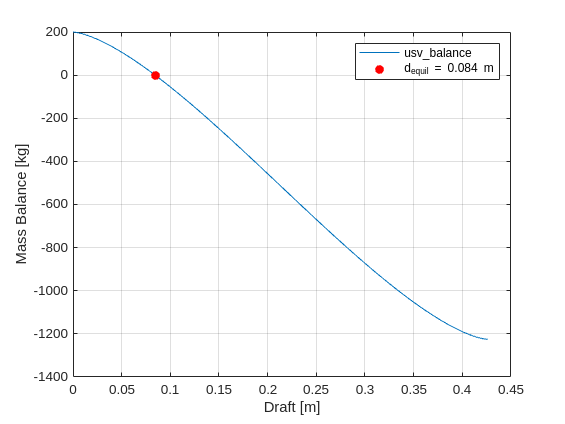

dd = linspace(0, 2*0.213);
bb = usv_balance(dd);
figure
plot(dd, bb)
hold on
plot(d_equil, usv_balance(d_equil), 'ro', 'MarkerFaceColor','r')
xlabel('Draft [m]')
ylabel('Mass Balance [kg]')
grid("on")
legend('usv\_balance', sprintf("d_{equil} = %.3f m",d_equil))